# lora sim script

This script is used to evaulate and generate graphs for snr , jammer and and doppler impact

## lora parameters

%clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
%numSym=round(50000/SF);
numSym=84;

randomData=false;
enableFilters=false;
%channel
perfectChannel=true;%no  awgn
maxDopplerShift=0;%0.5*Fs/(2^SF);%shift has to be less than 0.5*Fs/(2^SF) to have no impact
flatDoppler=true;%true: apply same shift to entire signal, false: add dopplerrate*t to shift between each sample
maxSNR=15; %signal to noise ratio in dB
jammer=true;
%loops
nLoops=1;
loopSNR=false;
SNRstepsize=2;
loopDoppler=true;
dopplerRate=38;
dopplerStepsize=dopplerRate/Fs;%dopplerrate*sampletime

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=0;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


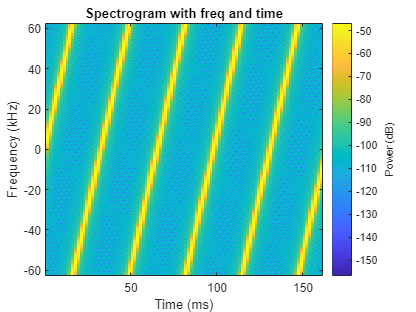

if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end


if enableFilters
    rolloff = 0.25;  % Roll-off factor for the RRC filter
    span = 6;  % Filter span in symbols
    L=8;
    rrcFilter = rcosdesign(rolloff, span, L);
    %impz(rrcFilter)
    txSignal= conv(loraSignal, rrcFilter, 'same');
else
    txSignal = loraSignal;
end

## channel & rx

rxSignal =   -0.3591 + 1.9646i  -1.8439 - 0.7362i   1.0873 - 1.6885i   1.4736 + 1.3693i  -1.6024 + 1.1759i  -0.8359 - 1.8092i   1.9528 - 0.4968i   0.1412 + 1.9968i  -1.9686 - 0.2497i   0.6336 - 1.9009i   1.7682 + 0.9650i  -1.2593 + 1.5427i  -1.2594 - 1.5390i   1.7681 - 0.9612i   0.6334 + 1.9048i  -1.9689 + 0.2537i   0.1408 - 1.9926i   1.9523 + 0.5012i  -0.8365 + 1.8139i  -1.6031 - 1.1709i   1.4727 - 1.3639i   1.0862 + 1.6943i  -1.8452 + 0.7424i  -0.3606 - 1.9579i   2.0139 + 0.0072i  -0.3612 + 1.9723i  -1.8463 - 0.7280i   1.0845 - 1.6798i   1.4704 + 1.3785i  -1.6060 + 1.1855i  -0.8400 - 1.7992i   1.9482 - 0.4863i   0.1361 + 2.0076i  -1.9744 - 0.2386i   0.6273 - 1.8895i   1.7611 + 0.9766i  -1.2671 + 1.5546i  -1.2679 - 1.5270i   1.7588 - 0.9491i   0.6233 + 1.9168i  -1.9799 + 0.2657i   0.1290 - 1.9808i   1.9395 + 0.5128i  -0.8502 + 1.8252i  -1.6178 - 1.1599i   1.4571 - 1.3535i   1.0697 + 1.7042i  -1.8626 + 0.7516i  -0.3789 - 1.9495i   1.9947 + 0.0147i


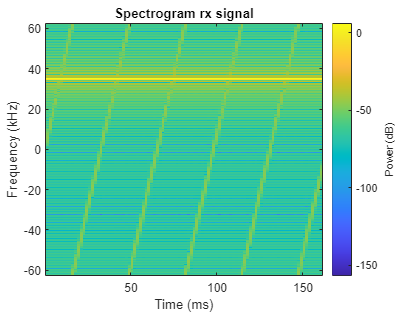

        1185        1185           0           0           0           0        1185        1185        1185        1185        1185           0           0           0        1185        1185        1185        1185        1185           0           0           0           0        1185        1185        1185        1185           0           0           0           0        1185        1185        1185        1185        1185           0           0           0        1185        1185        1185        1185        1185           0           0           0           0        1185        1185        1185        1185           0           0           0           0        1185        1185        1185        1185        1185           0           0           0        1185        1185        1185        1185        1185           0           0           0           0        1185        1185        1185        1185           0           0           0           0        1185        1185    

%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    else%apply dopper rate
        freqShift=zeros(1,length(t));
        
        for i=1:length(t)
            if loopDoppler
                freqShift(i)=maxDopplerShift+dopplerRate*counter*t(i);
            else
                freqShift(i)=maxDopplerShift+dopplerRate*t(i);
            end
        end
        %freqShift=linspace(dopplerShift,-dopplerShift,length(t));
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    end
    
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = txSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(txSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(txSignal,maxSNR,'measured'));
        end
        %snr
    end
    if jammer
        f1=35e3;
        rxSignal=rxSignal+2*exp(1j*2*pi*f1*t)
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols

        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    if enableFilters
        matchedFilter = rcosdesign(rolloff, span, L);
        rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
    else
        rxSignalFiltered = rxSignal;
    end
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignalFiltered,SF,numSym);
    if counter==nLoops
        disp(decodedSymbols)
    end
    errors(counter)=sum(messageBits~=decodedBits);
    firstErrorIndex(counter) = find(decimalSymbols ~= decodedSymbols, 1);%index of first error symbol
    SNR_linear = 10^(SNR / 10);
    EbN0_sim(counter)=10*log10(SNR_linear*Fs/bitRate);
end

lora_ber=errors/dataLength

lora_ber = 0.1865

## doppler estimation

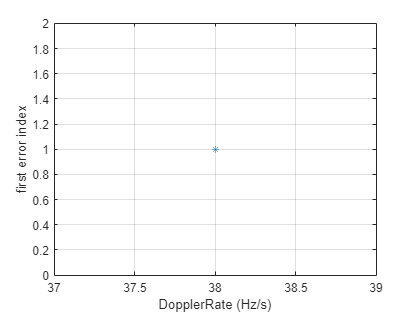

if loopDoppler
    semilogy((1:nLoops)*dopplerRate,lora_ber,'-*')
    xlabel('DopplerRate (Hz/s)')
    ylabel('Bit Error Rate')
    grid on

    plot((1:nLoops)*dopplerRate,firstErrorIndex,'*')
    xlabel('DopplerRate (Hz/s)')
    ylabel('first error index')
    grid on

end


symbolOffset=decodedSymbols-decimalSymbols;
preambleLength=20;
estDopplerOffset=(symbolOffset/2^SF)*Fs

estDopplerOffset = 1.0e+04 *

    3.6163    3.6163         0         0         0         0    3.6163    3.6163    3.6163    3.6163    3.6163         0         0         0    3.6163    3.6163    3.6163    3.6163    3.6163         0         0         0         0    3.6163    3.6163    3.6163    3.6163         0         0         0         0    3.6163    3.6163    3.6163    3.6163    3.6163         0         0         0    3.6163    3.6163    3.6163    3.6163    3.6163         0         0         0         0    3.6163    3.6163


symbolDuration=(2^SF)/Fs;
indices = round(linspace(1, length(freqShift), preambleLength));

freqShiftValues = freqShift(indices)

freqShiftValues =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



estDopplerRate=0.5*(estDopplerOffset(preambleLength)-estDopplerOffset(1))/(preambleLength*symbolDuration)

estDopplerRate = -2.7590e+04

symbolTimes=linspace(symbolDuration,preambleLength*symbolDuration,preambleLength)

symbolTimes =     0.0328    0.0655    0.0983    0.1311    0.1638    0.1966    0.2294    0.2621    0.2949    0.3277    0.3604    0.3932    0.4260    0.4588    0.4915    0.5243    0.5571    0.5898    0.6226    0.6554



correctedSymbols=round(decodedSymbols(1:preambleLength)-((estDopplerOffset(1)+estDopplerRate*symbolTimes)/Fs)*2^SF)

correctedSymbols =           30          59       -1096       -1067       -1037       -1007         207         237         267         296         326        -830        -800        -770         444         474         504         533         563        -593


## other method

if false

% Multiply the signal with its complex conjugate
% r = rxSignal .* conj(rxSignal);
% 
% angle(rxSignal)

z = rand(1, 81920) + 1i*rand(1, 81920); % Example complex vector

% Compute the conjugate of the signal
z_conj = conj(z);

% Multiply the signal with its complex conjugate
r = z .* z_conj;
% Number of samples
N = length(r);

% Indices for the 4 phases
indices = [N/4, N/2, 3*N/4, N];
phase1=angle(sum(rxSignal(1:indices(1))))
phase2=angle(sum(rxSignal(indices(1):indices(2))))
phase3=angle(sum(rxSignal(indices(2):indices(3))))
phase4=angle(sum(rxSignal(indices(3):indices(4))))

fd=((phase2+phase4)-(phase1+phase3))/(2*pi*N*(1/Fs))
rd=((phase4-phase3)-(phase2-phase1))/(pi*(N/2)^2 *(1/Fs)^2)
end

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula


lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 0.5595

lora_ber7=errors/dataLength

lora_ber7 = 0.1865

% lora_ber10=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    theoryBer12=0.5*qfunc((log(12)/log(12))/sqrt(2)*(SNRvec+10*log10((2^12)/12)));
    theoryBer7=0.5*qfunc((log(7)/log(12))/sqrt(2)*(SNRvec+10*log10((2^7)/7)));

    
    semilogy(SNRvec',theoryBer7,'--*')
    hold on
    %semilogy(SNRvec',lora_ber,'-*')
    
    
    %hold on
    semilogy(SNRvec',lora_ber7,'-*')
    semilogy(SNRvec',theoryBer12,'--g*')
    %semilogy(SNRvec',lora_ber10,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    
    %semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-4 1])
    %legend('theory 12','theory 7','SF 7','SF 9','SF 12')%adjust legend!
    legend( 'Theoretical BER SF 7','Empirical BER SF 7','Theoretical BER SF 12','Empirical BER SF 12')
    title('BER of LoRa Model VS Theory')

    EbN0=0:10;
    ber=berawgn(EbN0,"psk",4,"nondiff");
    figure
    semilogy(transpose(EbN0),ber,'-*')
    hold on
    semilogy(transpose(EbN0_sim),theoryBer7,'-+')
    semilogy(transpose(EbN0_sim),theoryBer12,'-+')
    legend({'Theoretical BER','Empirical BER'},'Location','best')
    xlabel('Eb/No (dB)')
    ylabel('Bit Error Rate')
    title('BER vs EbN0 lora vs ofdm')
    ylim([1e-10,1]);
    grid on
    
end

%% compare with nbiot


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*2^SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*2^SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/2^SF)*BW